# Functions

## What we've covered this week in Part 2

This week in Part 2 we learnt about:

- Programmatic plotting

- Plot options

- Customizing plot properties

- Specifying colour

- Axis control

- Plotting multiple columns

## Why Use Functions?

As the complexity of your scripts increases, you will most likely find that certain pieces of code are repeated in several different places. In this case, it makes sense to package this segment of code as a separate, general “helper” code that you can call with a single command. In this way you reduce maintenance effort: if you change this block of code, you now need change it in one place only.

It is possible to call scripts from within other scripts. However, this is generally not recommended as all scripts share the MATLAB (base) workspace. Hence, any change made to a variable by one script affects all the other scripts that reference that variable. Furthermore, you need to keep a careful inventory of your workspace so that all scripts are using the same variable names. This undermines the purpose of keeping your code modular to be more maintainable.

A better solution is to create your own functions. A function can be seen as a “black box”: code that requires certain types of inputs, performs some action, and returns some outputs. As it is running, you typically never see the actions “inside the box,” just the output. The variables in a function occupy their own, separate workspace.

## Creating and Calling Functions

###  **Creating a Function**

Any script can contain code to define a function. Functions are created using a function declaration.

`function [out1,`  `out2, ...] = function_name(in1, in2, ...)`

- The declaration starts with the function keyword.

- The function declaration syntax (after the function keyword) is identical to the syntax for calling functions in MATLAB. 

- For functions with a single output, the square brackets are unnecessary (and slightly less efficient). 

-  Values are assigned to input variables when the function is called with specific inputs. 

- Code following the function declaration describes how output variables are computed from input variables. 

- Each declared output must be assigned a value somewhere in the code.

- The function ends with an end statement.

Functions defined within a script are called local functions. Local function definitions must be located after all other script code. In the Live Editor, a section break is automatically created before the first local function definition. 

There are times when you may want to create a function that has no input or no output (or even both). To accommodate such situations, the following are all valid declaration syntaxes:

`function [out1, out2, ...] = function_name()`

`function [out1, out2, ...] = function_name`

`function function_name(in1, in2, ...)`

`function [] = function_name(in1, in2, ...)`

`function function_name`

`function function_name()`

`function [] = function_name`

`function [] = function_name()`

 Let’s look at an example of a function that takes in three values and performs addition calculations on the inputs and outputs the answers of these calculations. Find function here

Now you try! Create a function called “calculateConeVolume” that calculates the volume of a cone. Write the function here

### **Calling a Function**

User-defined functions are called just like any other MATLAB functions. The calling syntax is specified in the function declaration. 

The values of the inputs given when the function is called are assigned, in order, to the variables in the function declaration line: 

`[x, y] = myfunction(42, pi, 0);`

[x, y] = myfunction(42, pi, 0)

x = 45.1416

y = 3.1416

Inside `myfunction`, `a` will have the value 42, `b` will have the value `pi`, and `c`will have the value 0.

Similarly, the outputs are assigned in order. In the above example, the variable `frogs `inside the function will have the value 45.1416 and `bats `will have the value `pi`. Hence, in the base MATLAB workspace, `x` will be assigned the value 45.1416 and `y` will be assigned the value `pi`.

If a function is written to return multiple outputs, it is not necessary to return all the outputs. For example, if only the output `x` is needed, you can call `myfunction` by typing

`x = myfunction(42, pi, 0);`

x = myfunction(42, pi, 0)

x = 45.1416

Now `x` will be assigned the value 45.1416. The value assigned to bats inside the function (`pi`) will be ignored.

If only `y` is needed, however, you can tell MATLAB to ignore `x `by using the tilde (~) as a placeholder: 

`[~, y] = myfunction(42,pi, 0);`

[~, y] = myfunction(42,pi, 0)

y = 3.1416

Now `y` will be assigned the value `pi `because this is the value assigned to `bats `inside the function. The value assigned to `frogs `inside the function will be ignored. 

As always, if no return variable is specified when the function is called, the result is returned to the default variable `ans`. If the function returns more than one output, the first will be assigned to `ans` (and the others ignored).

Call your calculateConeVolume function giving it input values to use in the function

%Define input variables here
r = 8 %cm

r = 8

h = 18 %cm

h = 18

	
%Call function with input variables here
volume = calculateConeVolume(r, h)

volume = 1.2064e+03

## Function Workspaces

Functions operate within their own *function workspace*, separate from the *base workspace *accessed at the prompt or from within scripts. If a function calls another function, each maintains its own separate workspace. 

Because workspaces are kept separate, MATLAB passes variables by value. That is, when you make a call such as 

`a = foo(b)` 

to a function with a declaration line of 

`function y = foo(x) `

MATLAB passes the *value *of `b` into `foo`. The variable `x` in the `foo` workspace thus takes this value but is a separate variable to `b`(which resides in the base workspace). Hence, changes to `x`do not affect `b`. Similarly, once `foo` is done running, it copies the *value *currently in its variable `y` back to the workspace from which it was called, in this case into the base workspace variable `a`. Once the function is finished, its workspace is destroyed.

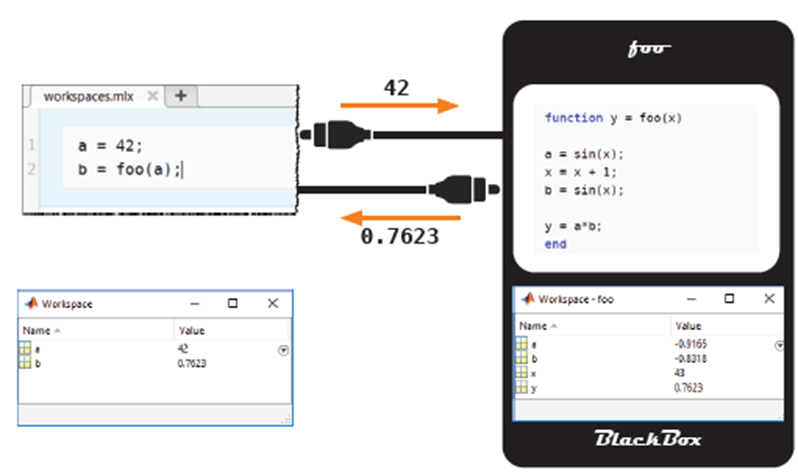

Check the workspace after you’ve called your calculateConeVolume function and verify that the original function variables are not in the base workspace and only the variables defined in your function call are present in the base workspace.

## Creating a Function File

Functions may also be saved in their own file. While local functions can only be accessed by the script in which they live, functions defined in function files can be called from the command line, live scripts, and other functions. 

Function files have one key syntactic element: function files always begin with the function declaration. 

- The keyword `function `must be the first (non-comment) code in the file. 

- To avoid confusion, the name of the function and the file name the function is saved in should always match. That is, to create a function named `function_name` the file should be named `function_name.mlx`. 

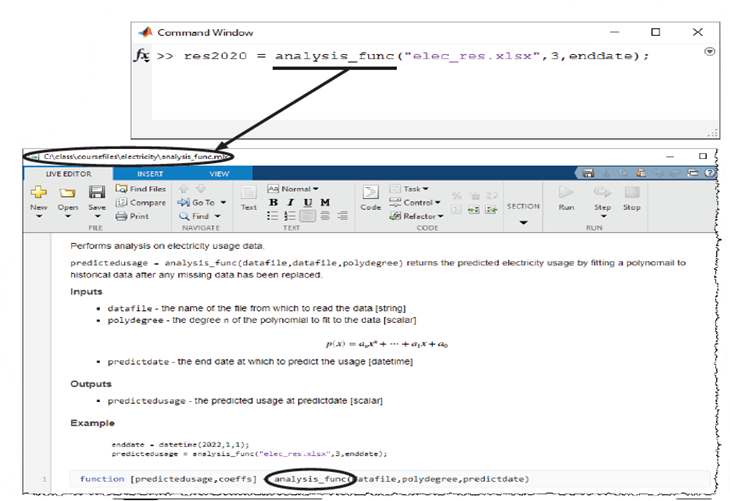

 **Note **MATLAB always uses the function definition that is saved on disk. Be sure to save any changes made to a function before calling it.

We’ve created a function file for the myfunction function declared earlier, we are now able to call it from the command line as it is now longer a local function.

`>>[x, y] = myfunction(42, pi, 0);`

Turn your calculateConeVolume function into a function file using the following steps:

- Create a new Live Script using the **New **drop-down menu in the File toolstrip section

- Copy-paste the calculateConeVolume code you wrote earlier into the new Live Script

- Save the new Live Script with the name identical to your function name, in the same folder the Week 5 Live Scripts are saved

Now try call your function from the command line and see if it works.

## Debugging & Error Handling

### **What is Debugging and Error Handling?**

In programming it is more likely than not that your code will produce some errors, this is the nature of writing code, it is error prone. Errors are also referred to as bugs in programming and therefore the process of finding them and correcting them is referred to as debugging.

Error handling is your program’s ability to counter or seize any errors that may have been brought about by the programmer or an actual problem. Error handling is a good way to ensure that your program is robust. 

### **Debugging in MATLAB**

Because function workspaces are local and temporary, finding problems with your code can be difficult. 

The MATLAB Editor has an integrated code analysis tool that provides a check for syntax errors as the code is being written. For example, strings missing a delimiter (“) are coloured red, while closed strings turn purple. Code inside loops is indented and closing parentheses are briefly highlighted with their opening counterpart. 

A small icon in the upper-right corner of the Editor warns when the code may contain a problem. 

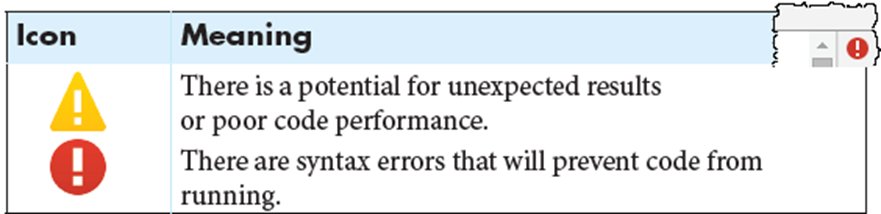

Additionally, specific problems within the code appear with an orange or red underline. A description is shown whenever the mouse is hovered over the highlighted code. Sometimes the message suggests a correction or improvement. 

Scripts and functions can invoke other scripts and functions. Hence, when errors do occur, they may originate several layers deep into the progression of function calls. As mentioned in Week 1, in the “Basic Debugging in MATLAB” sub-section, MATLAB shows a *stack trace*, which is a list of the error messages from each function. Careful review of this stack trace may reveal the source of the error. 

Error messages in MATLAB give the line number where the error occurred. Clicking the error message will open the appropriate file in the Editor.

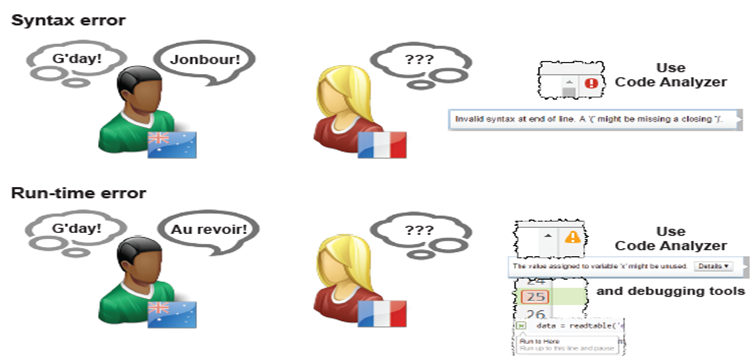

View a version of myfunction that has a bug in it (myfunction_debug.mlx). Use the Code Analyzer messages to find the potential problems. Try to call the function in the command line. Did it work? If not, follow the error message link to find where the problem occurred.

`>>[x, y] = myfunction_debug(42, pi, 0);`

Fix the bug in myfunction_debug and try calling it again from the command line.

### **Error Handling**

Using a [try/catch](https://www.mathworks.com/help/matlab/ref/try.html) statement to execute code after your program encounters an error or using the [error](https://www.mathworks.com/help/matlab/ref/error.html) built-in function to print error messages to the command line are two common ways of error handling.

try/catch statements can be useful if you:

- Want to finish the program in another way that avoids errors

- Need to clean up unwanted side effects of the error

- Have many problematic input parameters or commands

Arrange try/catch statements into blocks of code, like this pseudocode:

try

  *try block*...

catch

  *catch block*...

end

If an error occurs within the *try block*, MATLAB skips any remaining commands in the try block and executes the commands in the *catch block*. If no error occurs within the *try block*, MATLAB skips the entire *catch block*.

Let’s look at an example of a try/catch statement. 

Consider the combinations function that returns the number of combinations of k elements from n elements. Find the function here.

C = combinations(4, 8)

MATLAB throws an error whenever k > n. You cannot construct a set with more elements, k, than elements you possess, n. Using a try/catch statement, you can avoid the error and execute this function regardless of the order of inputs. See robust_combine function here.

robust_combine treats any order of integers as valid inputs:

C1 = robust_combine(8, 4)
C2 = robust_combine(4, 8)

You can throw an error to flag fatal problems within the program using the error function. After displaying the message, MATLAB stops the execution of the current program.

Let’s use the combinations function to display an error message in the command window.

As mentioned previously, such a function is nonsensical if k > n; you cannot choose 8 elements if you start with just 4. You must incorporate this fact into the function to let anyone using combinations know of the problem. Find the function here.

If the combinations function receives invalid input, MATLAB stops execution immediately after throwing the error message:

combinations_with_error(4, 8)

Adding run-time parameters to your errors can clarify the problems within a program. Consider the function combinations, you can throw a much more informative error using run-time parameters. Find the function here.

If this function receives invalid arguments, MATLAB throws an error message and stops the program:

combinations_with_runtime_parameters(6, 9)

Open the function file **sentenceMaker.mlx**. This function receives a cell array of character arrays and returns a sentence stored in a single row character vector made up of the words in each cell. For example, if the input cell array is:

`words = {``'Hello,' ``; ``'how'``; ``'are'``; ``'you'``; ``'doing?'``}`

then the function should return the character array:

`sentence = ``'Hello, how are you doing?'`

In **sentenceMaker_error.mlx**, write an if-statement in the function that checks if the input to the function is ***not*** a cell array (Hint: use the [iscell](https://www.mathworks.com/help/matlab/ref/iscell.html) built-in function), and if it’s not, write an error message telling the user that the input must be a cell array.

Call **sentenceMaker_error** in the command line as follows and check that you get the error message you specified:

sentenceMaker_error([‘Hello world!’])

## What we've covered this week in Part 3

This week in Part 3 we learnt about:

- Why we use functions

- Creating and calling functions

- Function workspaces

- Creating a function file

- Debugging and error-handling

## Creating a Function Examples and Exercises

Creating function example:

function [frogs, bats] = myfunction(a, b, c)
frogs = a + b;
bats = b + c;
end

Write calculateConeVolume function here:

function coneVolume = calculateConeVolume(radius, height)

coneVolume = (1/3)*pi*(radius^2)*height;

end

## Debugging and Error-Handling Examples and Exercises

combinations function:

function com = combinations(n, k)
    com = factorial(n)/(factorial(k)*factorial(n - k));
end

robust_combine function:

function com = robust_combine(n, k)
    try
       com = factorial(n)/(factorial(k)*factorial(n - k));
    catch
       com = factorial(k)/(factorial(n)*factorial(k - n));
    end
end

combinations function with an error message:

function com = combinations_with_error(n, k)
    if k > n
        error('Cannot calculate with given values')
    end
    com = factorial(n)/(factorial(k)*factorial(n - k));
end

combinations function with runtime parameters:

function com = combinations_with_runtime_parameters(n, k)
    if k > n
        error('Cannot choose %i from %i elements', k, n)
    end
    com = factorial(n)/(factorial(k)*factorial(n - k));
end